clear

# `Part: A    Source Data`

source = "Text file"

source = "Text file"


 

if (source == "Random bits")
    d = randi(15, 1, 128)
    data = dec2bin(d)-'0'
end
if (source == "Text file")
    [file, path] = uigetfile("*.txt");  %open a text file
    fileID = fopen(strcat(path, "/", file));
    text = fscanf(fileID, '%c')
    data = dec2bin(text, 8)-'0'
    fclose(fileID);
end

text =     'Hello, My name is Shyam Poduval       
     ID-2020A3PS0445G
     This text is created in order to fill the requirements of the course Modern Communication Technology  '


data =      0     1     0     0     1     0     0     0
     0     1     1     0     0     1     0     1
     0     1     1     0     1     1     0     0
     0     1     1     0     1     1     0     0
     0     1     1     0     1     1     1     1
     0     0     1     0     1     1     0     0
     0     0     1     0     0     0     0     0
     0     1     0     0     1     1     0     1
     0     1     1     1     1     0     0     1
     0     0     1     0     0     0     0     0


if (source == "Image")
    [file, ~] = uigetfile("*");  %open a image file
    im = imread(file);
    im = rgb2gray(im);
    im = imresize(im, [64, 64]);
    data = dec2bin(im)-'0'
end
if (source == "Audio")
    %[file, ~] = uigetfile("*");
    %[y,Fs] = audioread(file);
    recordedObject = audiorecorder;
    disp("Recording started....")
    recordblocking(recordedObject, 10);
    Fs = recordedObject.SampleRate;
    disp('End of Recording.');
    y = getaudiodata(recordedObject)
    sign_of_y = sign(y);
    y = abs(y);
    data = fix(rem(y*pow2(-(8-1):8),2))
    %data = data(1:32768)
end

dim_before_coding = size(data);

# `Part: B    Channel Coding`

global coding;
coding = "(7, 4) hamming code"

coding = "(7, 4) hamming code"


 

if (coding == "(7, 4) hamming code")
    bits = reshape(data, [], 4);
    coded_data = encode(bits, 7, 4)
    disp("Encoded with (7, 4) hamming code")
end

coded_data =      1     1     1     0     0     1     0
     0     1     1     0     1     0     0
     1     0     0     0     1     1     0
     1     0     0     0     1     1     0
     0     0     1     0     1     1     1
     1     0     0     0     1     1     0
     0     1     1     0     1     0     0
     1     1     1     0     0     1     0
     1     0     0     0     1     1     0
     0     1     1     0     1     0     0


Encoded with (7, 4) hamming code


if (coding == "BCH (127, 64) code")
    bits = reshape(data, [], 64);
    bits = gf(bits);
    coded_data = bchenc(bits, 127, 64)
    disp("Encoded with BCH (127, 64) code")
    
    % (1536, 127)
end

dim_after_coding = size(coded_data);

# `Part: C   Modulation`

modulation = "16 QAM"

modulation = "16 QAM"


 

if (modulation == "16 FSK")
    modulating_signal = reshape(coded_data, 4, []);
    modulating_signal = binaryToDecimal(modulating_signal);
    modulated_signal = fskmod(modulating_signal, 16, 0.05, 4)
    disp("16 FSK modulation applied")
end
if (modulation == "16 PSK")
    modulating_signal = reshape(coded_data, 4, []);
    modulating_signal = binaryToDecimal(modulating_signal);
    modulated_signal = pskmod(modulating_signal, 16)
    disp("16 PSK modulation applied")
end
if (modulation == "16 QAM")
    modulating_signal = reshape(coded_data, 4, []);
    modulating_signal = binaryToDecimal(modulating_signal);
    modulated_signal = qammod(modulating_signal, 16)
    disp("16 QAM modulation applied")
end

modulated_signal =    1.0000 + 1.0000i   3.0000 - 3.0000i  -3.0000 + 1.0000i   3.0000 + 1.0000i   1.0000 + 1.0000i  -1.0000 + 1.0000i  -3.0000 + 3.0000i  -1.0000 + 1.0000i  -3.0000 + 3.0000i  -1.0000 + 3.0000i   1.0000 + 1.0000i  -3.0000 - 3.0000i  -1.0000 + 1.0000i   3.0000 + 3.0000i   3.0000 + 1.0000i  -3.0000 - 1.0000i  -3.0000 - 3.0000i   3.0000 - 1.0000i  -3.0000 + 1.0000i   3.0000 + 3.0000i   3.0000 + 3.0000i  -1.0000 + 3.0000i   3.0000 + 3.0000i  -1.0000 - 1.0000i  -3.0000 - 3.0000i  -3.0000 + 1.0000i   3.0000 - 1.0000i   3.0000 + 3.0000i  -1.0000 + 3.0000i  -3.0000 - 3.0000i   3.0000 + 1.0000i   3.0000 + 1.0000i   3.0000 + 3.0000i  -1.0000 + 3.0000i  -3.0000 - 1.0000i  -3.0000 - 1.0000i  -3.0000 + 1.0000i   1.0000 + 3.0000i  -1.0000 + 3.0000i  -3.0000 - 1.0000i  -3.0000 - 1.0000i   3.0000 - 1.0000i  -3.0000 + 3.0000i  -3.0000 - 1.0000i   3.0000 + 3.0000i  -1.0000 + 3.0000i   3.0000 - 1.0000i  -3.0000 + 3.0000i  -3.0000 + 3.0000i  -3.0000 + 3.0000i


16 QAM modulation applied


if (modulation == "32 QAM")
    modulating_signal = reshape(coded_data, 4, []);
    modulating_signal = binaryToDecimal(modulating_signal);
    modulated_signal = qammod(modulating_signal, 32)
    disp("32 QAM modulation applied")
end

global dim_after_modulation;
dim_after_modulation = size(modulated_signal);

# `Part. D   Display Transmitted data parameters before adding noise`

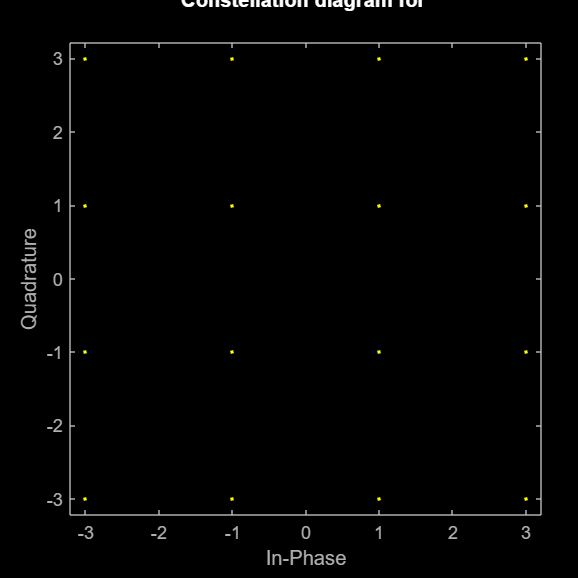


 

if (modulation == "16 PSK" || modulation == "16 QAM")
    scatterplot(modulated_signal)
    title("Constellation diagram for ", modulation)
end


if (source == "Text file")
    disp(text)
end

Hello, My name is Shyam Poduval       
ID-2020A3PS0445G
This text is created in order to fill the requirements of the course Modern Communication Technology  


if (source == "Image")
    imshow(im)
end
if (source == "Audio")
    figure;
    subplot(2, 1, 1)
    plot(y)
    xlabel("t")
    ylabel("x(t)")
    title("Audio Signal")
    
    subplot(2, 1, 2)
    x = y;
    N = length(x);
    xdft = fft(x);
    xdft = xdft(1:N/2+1);
    psdx = (1/(Fs*N)) * abs(xdft).^2;
    psdx(2:end-1) = 2*psdx(2:end-1);
    freq = 0:Fs/length(x):Fs/2;

    plot(freq,10*log10(psdx))
    grid on
    title('Periodogram Using FFT')
    xlabel('Frequency (Hz)')
    ylabel('Power/Frequency (dB/Hz)')
end

SNR = 20

SNR = 20


 

transmitted_signal = awgn(modulated_signal, SNR, 'measured')

transmitted_signal =    1.1248 + 0.9039i   3.4256 - 3.1017i  -3.5242 + 1.4649i   3.2001 + 1.2207i   1.0740 + 0.8997i  -1.3035 + 1.1506i  -3.1006 + 2.9164i  -0.9205 + 1.1638i  -2.1696 + 3.3286i  -0.3573 + 2.6276i   0.6867 + 1.2388i  -2.2957 - 2.6616i  -0.8317 + 1.0110i   2.9854 + 3.4053i   3.1659 + 1.0361i  -3.0476 - 1.2871i  -3.0288 - 3.5090i   3.3457 - 1.0774i  -2.6730 + 1.1656i   3.3289 + 3.0737i   3.1558 + 3.0960i  -1.2802 + 2.8661i   3.1665 + 3.0334i  -0.6217 - 1.3803i  -2.8865 - 3.1764i  -2.7599 + 0.8100i   3.1687 - 0.8794i   2.9296 + 2.9967i  -0.9318 + 2.7318i  -3.1827 - 3.0022i   3.2062 + 0.8399i   2.7338 + 0.8453i   2.7519 + 3.2005i  -1.1879 + 3.0263i  -3.6833 - 0.9076i  -2.6662 - 0.7949i  -2.9245 + 1.0418i   0.8248 + 3.1278i  -0.6820 + 3.1585i  -3.3972 - 0.7283i  -3.0237 - 0.8896i   2.9440 - 0.6723i  -2.9259 + 3.0052i  -2.9274 - 1.0111i   2.7993 + 3.3948i  -1.0070 + 2.8817i   2.9617 - 1.0007i  -2.8543 + 3.2135i  -2.7463 + 3.0348i  -2.7426 + 3.3260i


# `Display Transmitted data parameters after adding noise`

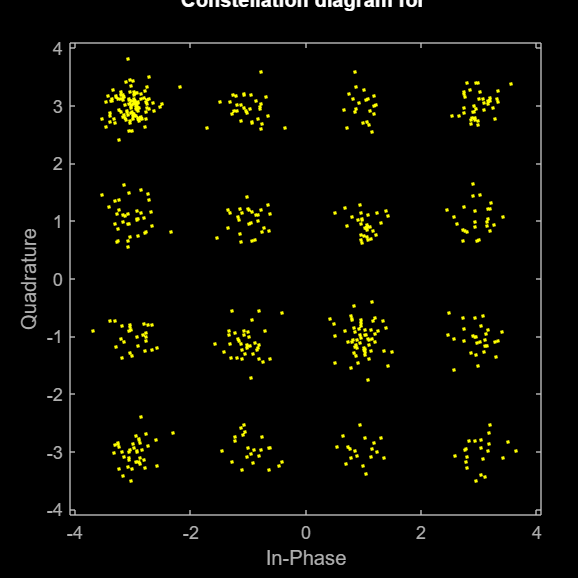

 

if (modulation == "16 PSK" || modulation == "16 QAM")
    scatterplot(transmitted_signal)
    title("Constellation diagram for ", modulation)
end

# `Part F    Demodulate the data`


 

if (modulation == "16 FSK")
    demodulated_signal = fskdemod(transmitted_signal, 16, 0.05, 4)
    disp("Demodulation - 16 FSK")
end
if (modulation == "16 PSK")
    demodulated_signal = pskdemod(modulated_signal, 16)
    disp("16 PSK demodulation")
end
if (modulation == "16 QAM")
    demodulated_signal = qamdemod(modulated_signal, 16)
    disp("16 QAM demodulation")
end

demodulated_signal =     13    10     1     9    13     5     0     5     0     4    13     2     5     8     9     3     2    11     1     8     8     4     8     7     2     1    11     8     4     2     9     9     8     4     3     3     1    12     4     3     3    11     0     3     8     4    11     0     0     0


16 QAM demodulation


if (modulation == "32 QAM")
    demodulated_signal = qamdemod(modulated_signal, 32)
    disp("32 QAM demodulation")
end

dim_after_demodulation = size(demodulated_signal);

demodulated_signal2 = changeShapeAfterDemodulation(demodulated_signal);

# `Part G   Decode the data`


 

if (coding == "(7, 4) hamming code")
    temp = reshape(demodulated_signal2, dim_after_coding(1), dim_after_coding(2));
    decoded_signal = decode(temp, 7, 4, "hamming/binary")
    disp("Decoded using (7, 4) hamming code")
    
end

decoded_signal =      0     0     1     0
     0     1     0     0
     0     1     1     0
     0     1     1     0
     0     1     1     1
     0     1     1     0
     0     1     0     0
     0     0     1     0
     0     1     1     0
     0     1     0     0


Decoded using (7, 4) hamming code


if (coding == "BCH (127, 64) code")
    temp = reshape(demodulated_signal2, dim_after_coding(1), dim_after_coding(2));
    temp = gf(temp);
    decoded_signal = bchdec(temp, 127, 64);
    decoded_signal = decoded_signal.x
    disp("Decoded using BCH (127, 64) code")
end

decoded_signal2 =reshape(decoded_signal, dim_before_coding(1), dim_before_coding(2))

decoded_signal2 =      0     1     0     0     1     0     0     0
     0     1     1     0     0     1     0     1
     0     1     1     0     1     1     0     0
     0     1     1     0     1     1     0     0
     0     1     1     0     1     1     1     1
     0     0     1     0     1     1     0     0
     0     0     1     0     0     0     0     0
     0     1     0     0     1     1     0     1
     0     1     1     1     1     0     0     1
     0     0     1     0     0     0     0     0


 
ber_with_coding = sum(decoded_signal2 ~= data, "all") / (numel(data))

ber_with_coding = 0

# `Reconstruct Signal`


 

if (source == "Random bits")
    reconstructed_signal = bi2de(decoded_signal2, 'left-msb')
end
if (source == "Text file")
    text = binaryToText(decoded_signal2);
    text = char(text);
    reconstructed_signal2 = convertCharsToStrings(text)
end

reconstructed_signal2 =     "Hello, My name is Shyam Poduval       
     ID-2020A3PS0445G
     This text is created in order to fill the requirements of the course Modern Communication Technology  "


if (source == "Image")
    decimals = binaryToText(decoded_signal2);
    reconstructed_signal2 = reshape(decimals, 64, 64);
    recovered_image = mat2gray(reconstructed_signal2);
    imshow(recovered_image)
end
if (source == "Audio")
    decoded_signal2 = decoded_signal2 * pow2(8-1:-1:-8).'
    sound(decoded_signal2, 8000, 8)
end

%function out = typecasting(inp)
%    dim = size(inp);
%    out = zeros(dim(1), dim(2));
%    for i = 1:dim(1)
%        out(i, :) = typecast(inp(i, :), "int32");
%    end
%end


function text = binaryToText(inp)
    dim = size(inp);
    dim = dim(1);
    text = zeros(dim, 1);
    for i = 1:dim
        sum = 0;
        for j = 1:8
            sum = sum + inp(i, j) * 2^(8 - j);
        end
        text(i) = sum;
    end
end

function y = changeShapeAfterDemodulation(inp)
    global dim_after_modulation;
    dim = [4, dim_after_modulation(2)];
    y = zeros(dim);
    for i = 1:dim_after_modulation(2)
        x = dec2bin(inp(i), 4);
        for j = 1:4
            y(5-j, i) = str2double(x(j));
        end
    end
end

function arr = binaryToDecimal(inp)
    if (class(inp) == "gf")
        inp = inp.x;
    end
    dim = size(inp);
    arr = zeros(1,dim(2));
    
    for i = 1:dim(2)
        vect = inp(:, i);
        for j = 1:length(vect)
            arr(i) = arr(i) + vect(j)*2^(j-1);
        end
    end
end